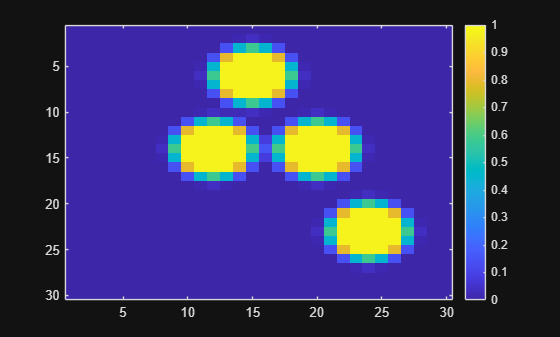

% Parameters
params.GridSize = 30;
params.RndFire = 4;
params.SpreadRate = 0.1;
params.DecayRate = .02;

% Function called
fire = init_fire(params);

% Update the plot each step
for step = 1:100;
    fire = fire_step(fire, params);

    imagesc(fire.intensity);
    colorbar;
    clim([0, 1]);
    pause(0.3);
end